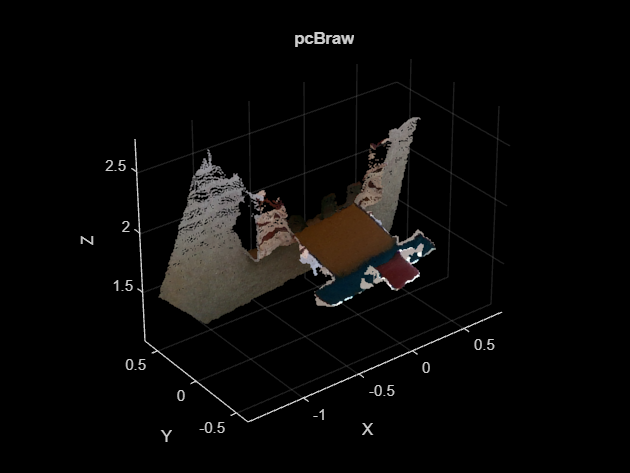

pcAraw = pcread("RealsenseA2.ply");
pcBraw = pcread("RealsenseB2-cleaned.ply");

pcshow(pcBraw, "AxesVisibility","on")
xlabel('X');
ylabel('Y');
zlabel('Z');
title("pcBraw")


pcB = realsense_to_LiDAR(pcBraw);
pcA = realsense_to_LiDAR(pcAraw)

pcA =   pointCloud with properties:

     Location: [78181×3 single]
        Count: 78181
      XLimits: [1.1750 4.1510]
      YLimits: [-2.2945 1.4236]
      ZLimits: [-0.6402 0.6998]
        Color: [78181×3 uint8]
       Normal: []
    Intensity: []


pcshow(pcB, "AxesVisibility","on")
xlabel('X');
ylabel('Y');
zlabel('Z');
title("pcB")
%brush('on')
view([-75.650 -4.472]);
pl = selectdata('selectionmode','brush');

Error using waitforbuttonpress
waitforbuttonpress exit because target figure has been deleted

Error in selectdata (line 506)
      waitforbuttonpress;

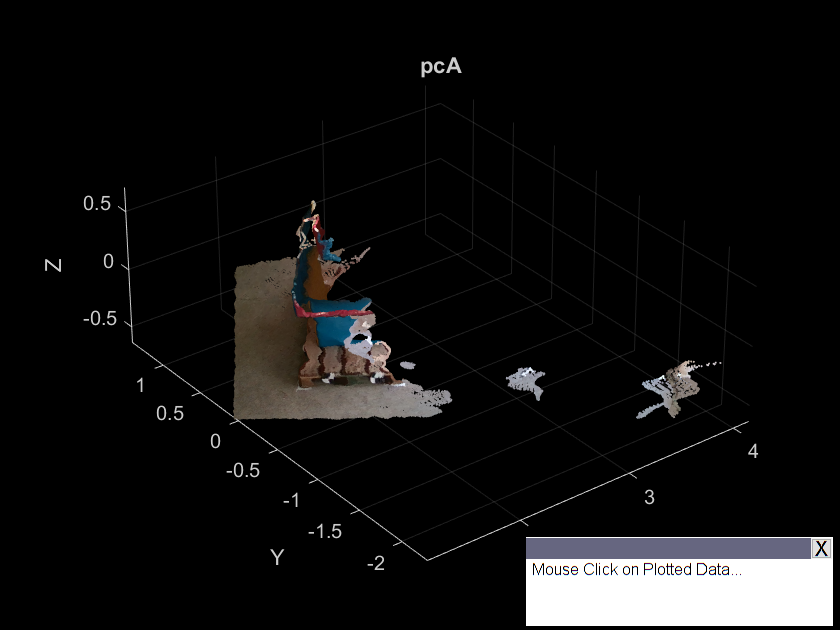

figure
pcshow(pcA, "AxesVisibility","on")
xlabel('X');
ylabel('Y');
zlabel('Z');
title("pcA")
dcm = datacursormode;
dcm.Enable = 'on';
dcm.DisplayStyle = 'window'

;
%[pl,xs,ys] = selectdata('sel','r');

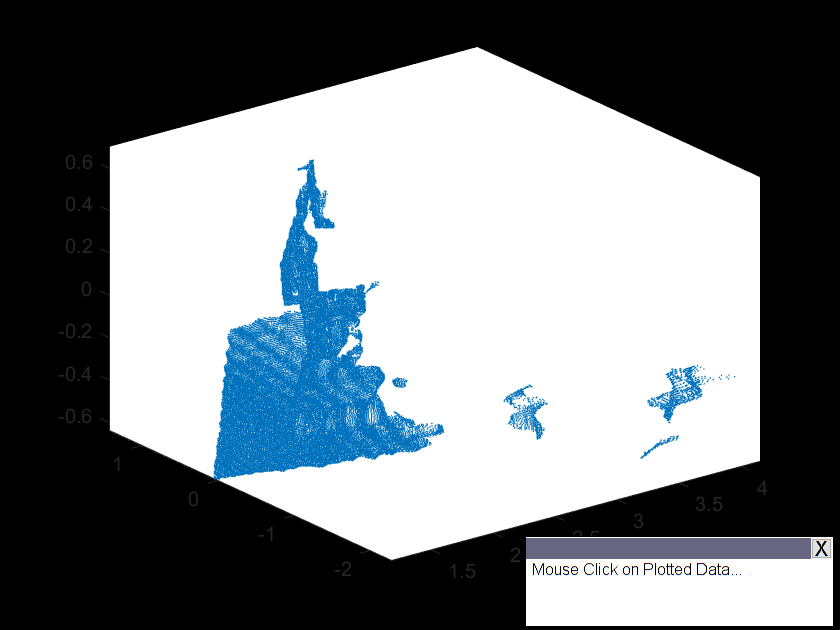

ln = plot3(pcA.Location(:,1),pcA.Location(:,2), pcA.Location(:,3), 'o');
ln.MarkerSize =0.5;
%c=validatecolor(pcA.Color, "multiple");
%ln.Color = c;
axis tight
dcm = datacursormode;
dcm.Enable = 'on';
dcm.DisplayStyle = 'window';

dcmObj = datacursormode(gcf);
dcmStruc = getCursorInfo(dcmObj);